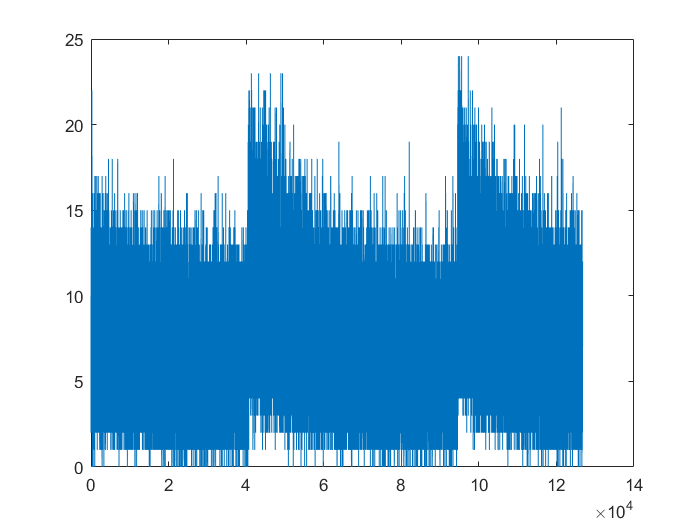

%Lab 4 - Kyle McEleney

%1.1 
mydata = h5read("gammaray_lab4.h5",'/data');

plot(mydata(1:507000/4,4))

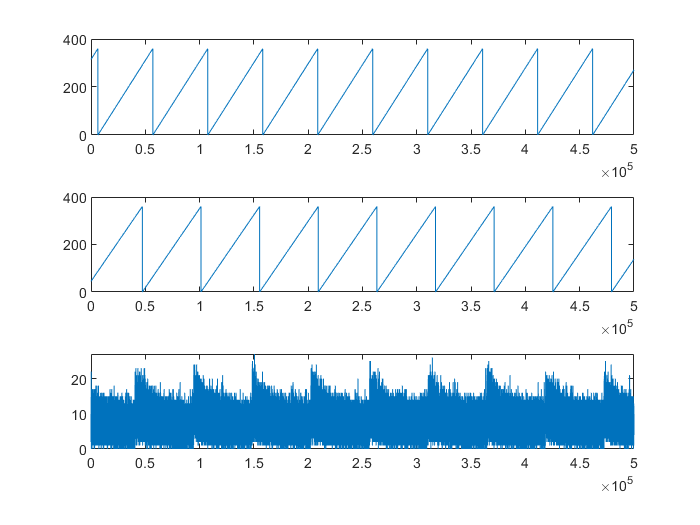


subplot(3, 1, 1);
plot(mydata(1:500000, 2))
subplot(3, 1, 2);
plot(mydata(1:500000, 3))
subplot(3, 1, 3);
plot(mydata(1:500000, 4))

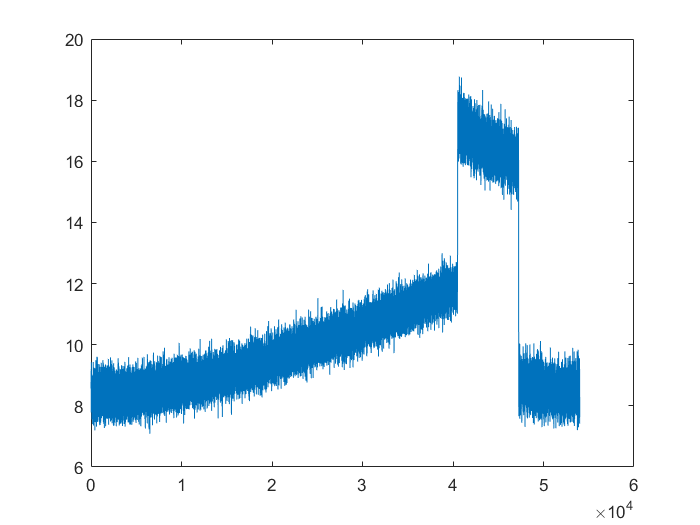

% The spike in gamma ray counts seems to coincide with the resetting of 
% the Earth's longitudinal position. Generally, there seems to be a periodic spike in 
% ray counts followed by a trailing off of counts to some nominal value
% around 15.

% Generate a Poisson distribution to fit the number of Gamma Ray counts
% column of the data.
dist = fitdist(mydata(:, 4), 'Poisson');

x = 1:30;
subplot(1,1,1)
plot(x, pdf(dist,x),"LineWidth",2)

% Determine lambda of each longitudinal position's count data.
longitudinal_data = transpose(mydata(1:54000, 3));
%Step through the data to pull out all gamma values given a longitudinal
%value

%initialize j to keep track of longitudinal phase and k to step through
%rows 

j = 1;
k = 2;
for i = 1:2592001
    longitudinal_data(k, j) = mydata(i,4);
    if j < 54000
        j = j+1;
    else
        j = 1;
        k = k+1;
    end
end

% Make distribution for each value of the longitude

lambda = transpose(mydata(1:54000, 3));
for m = 1:54000
    tempDist = fitdist(longitudinal_data(:, m), 'Poisson');
    lambda(2, m) = tempDist.lambda;
end

%Generate poisson distribution of the lambda values calculated for all
%longitudinal data points.
Lambda_poisson = fitdist(transpose(lambda(2, :)),'Poisson');

%Plot of pdf of all longitudinal data points by value.
plot(x, pdf(Lambda_poisson,x),"LineWidth",2)
% Plot of all lambda values vs longitudinal location
plot(lambda(2,:))

% Once the longitude goes to zero 47250, the gamma counts drop
% significantly. There is also a significant jump around 40500 where the
% lambda value goes from about 12 to roughly 17.
 